# Author: Lu, Chia-Feng 2013.11.28

clear, close all
clc

## initialize parameters

samplerate=500; % in Hz
N=1000; % data length

freq1=5; % in Hz
freq2=7; % in Hz
taxis=[1:N]/samplerate;

PCnum=2;  % the number of PC used to reconstruct signals

## generate test signals

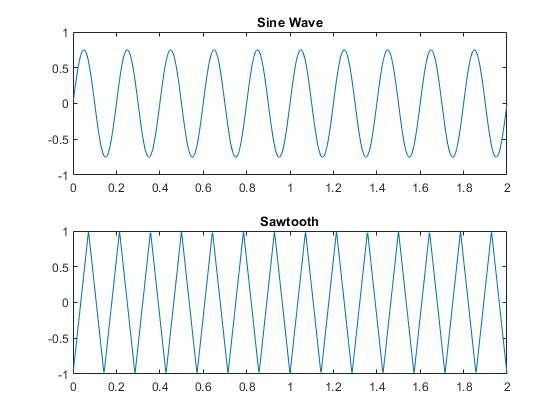

C1 = 0.75*sin(2*pi*freq1*taxis);        % 1st component: a sine wave
C2 = sawtooth(2*pi*freq2*taxis,0.5);    % 2nd component: a triangular wave

figure, 
subplot(211)
plot(taxis, C1)
title("Sine Wave")

subplot(212)
plot(taxis, C2)
title("Sawtooth")

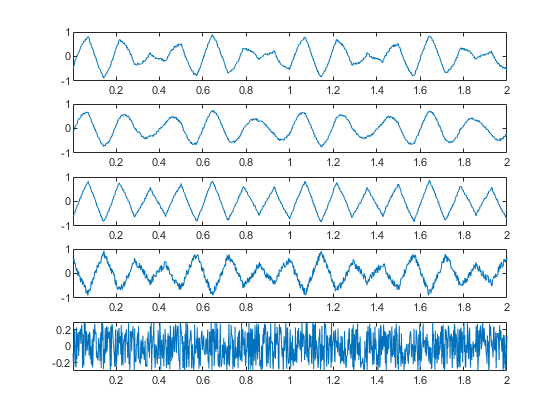


% Combine data in different proportions
X(1,:) = 0.5*C1 + 0.5*C2 + 0.1*rand(1,N);
X(2,:) = 0.7*C1 + 0.2*C2 + 0.1*rand(1,N);
X(3,:) = 0.2*C1 + 0.7*C2 + 0.1*rand(1,N);
X(4,:) = -0.3*C1 - 0.6*C2 + 0.3*rand(1,N);
X(5,:) = 0.6*rand(1,N);    % Noise only

% Center data by subtracting mean
X = X - mean(X,2)*ones(1,N);

figure, 
for i=1:size(X,1)
    subplot(size(X,1),1,i)
    plot(taxis,X(i,:)),xlim([taxis(1) taxis(end)])
end

## Principal Components Analysis using princomp funcion (using eig and svd)

[U,PC,eigenVal]=pca(X')

U =     0.5266    0.1589    0.0041    0.2567    0.7947
    0.4229    0.7920    0.0242    0.0030   -0.4396
    0.5305   -0.5167   -0.0165    0.5259   -0.4180
   -0.5120    0.2828   -0.0270    0.8104    0.0211
   -0.0175   -0.0208    0.9992    0.0294    0.0010


PC =    -0.8942    0.2703    0.1169   -0.1260   -0.0349
   -0.8917    0.3263   -0.3068    0.0177   -0.0045
   -0.7516    0.2645    0.1603    0.0486    0.0010
   -0.6012    0.2614    0.2545   -0.1212    0.0721
   -0.4583    0.2841   -0.2948   -0.0970    0.0326
   -0.5807    0.3409    0.1892    0.0836    0.0030
   -0.3112    0.3242    0.1610    0.0216    0.0127
   -0.2002    0.2897    0.3045   -0.1251    0.0526
   -0.0934    0.3161   -0.1551   -0.1251   -0.0196
    0.0137    0.2866    0.2596   -0.0572   -0.0095


eigenVal =     0.5450
    0.0852
    0.0308
    0.0052
    0.0008


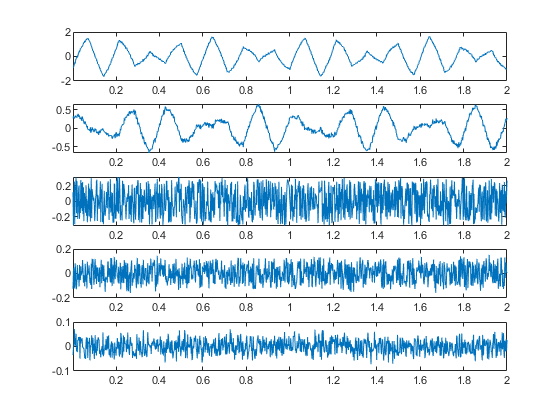


for i=1:size(X,1)
    eigen_perc(i)=sum(eigenVal(1:i))/sum(eigenVal)*100;  % calculate accumulated percentage of eigenvalues
end

figure, 
for i=1:size(PC,2)
    subplot(size(PC,2),1,i)
    plot(taxis,PC(:,i)),xlim([taxis(1) taxis(end)])
end

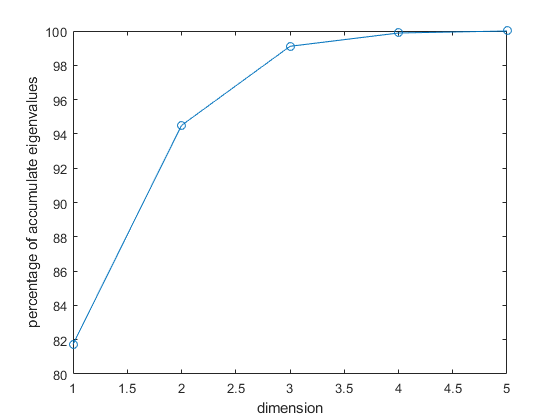


figure,plot(eigen_perc,'-o')
xlabel('dimension'),ylabel('percentage of accumulate eigenvalues')

## Check the covariance of principal components (PC)

cov(PC)  % make sure if the PCs are uncorrelated !

ans =     0.5450   -0.0000    0.0000   -0.0000   -0.0000
   -0.0000    0.0852   -0.0000   -0.0000   -0.0000
    0.0000   -0.0000    0.0308    0.0000   -0.0000
   -0.0000   -0.0000    0.0000    0.0052   -0.0000
   -0.0000   -0.0000   -0.0000   -0.0000    0.0008


% the off-diagonal terms should be 0

## Reconstruct the Signal only use the first PCnum PCs

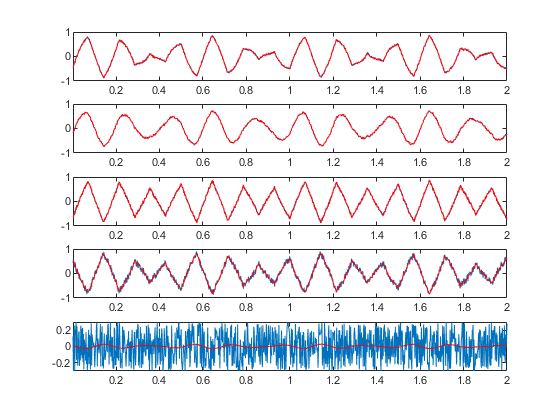

newX = U(:,1:PCnum)*PC(:,1:PCnum)';

figure, 
for i=1:size(newX,1)
    subplot(size(newX,1),1,i)
    plot(taxis,X(i,:)),hold on
    plot(taxis,newX(i,:),'r'),xlim([taxis(1) taxis(end)])
end